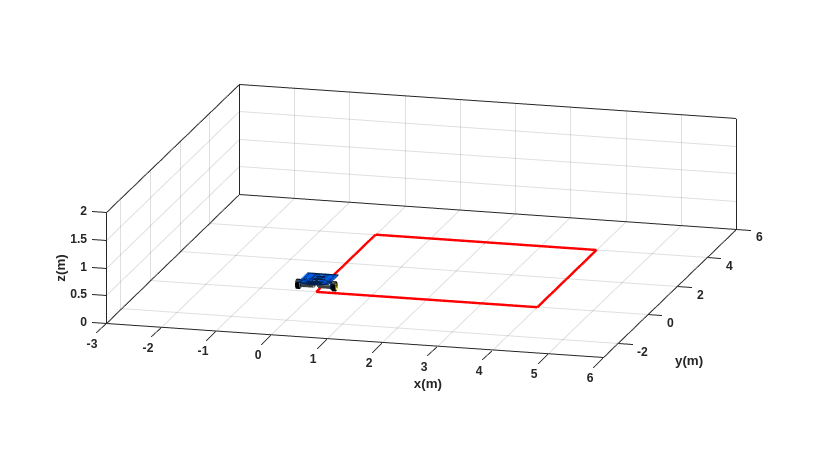

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tf = 20;             % Tiempo de simulacion en segundos (s)
ts = 0.1;            % Tiempo de muestreo en segundos (s)
t = 0: ts: tf;       % Vector de tiempo
N = length(t);       % Muestras

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros (1,N+1);  % Posici�n en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros (1,N+1);  % Posici�n en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

x1(1) = 0;    % Posicion inicial eje x
y1(1) = 0;   % Posicion inicial eje y
phi(1) =0;   % Orientacion inicial del robot

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1, N+1);  % Posicion en el punto de control (eje x) en metros (m)
hy = zeros(1, N+1);  % Posicion en el punto de control (eje y) en metros (m)

hx(1) = x1(1); % Posicion en el punto de control del robot en el eje x
hy(1) = y1(1); % Posicion en el punto de control del robot en el eje y

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

% Parámetros de los giros y movimientos
angles = [0, pi/2, pi/2, pi/2]; % Ángulos de giro (puedes modificarlos)
distances = [4, 4, 4, 4]; % Distancias de los movimientos lineales en metros (puedes modificarlas)
duration_turn = [1/ts, 1/ts, 1/ts, 1/ts];     % Duración de cada giro (puedes ajustarlo)
duration_lineal = [4, 4, 4, 4]; % Duración de cada movimiento lineal en segundos (puedes ajustarlo)

u = zeros(1,N); % Velocidad lineal (m/s)
w = zeros(1,N); % Velocidad angular (rad/s)

% Generación de las velocidades de referencia
idx_start = 1;
for i = 1:length(angles)
    % Duración del giro
    idx_end_turn = idx_start + duration_turn(i) - 1; % Índice final para el giro, ajustado por duration_turn(i)
    if idx_end_turn <= N
        w(idx_start:idx_end_turn) = angles(i) / (duration_turn(i) * ts); % Giro con el ángulo correspondiente
    end

    % Duración del movimiento rectilíneo
    % Calcular la velocidad lineal basada en la distancia y la duración
    velocity_linear = distances(i) / duration_lineal(i); % Velocidad lineal calculada

    % Duración variable basada en la distancia y la velocidad lineal
    duration_segment = duration_lineal(i) / ts; % Duración en términos de muestras
    idx_start_move = idx_end_turn + 1;
    idx_end_move = idx_start_move + duration_segment - 1; % Duración del movimiento rectilíneo

    if idx_end_move <= N
        u(idx_start_move:idx_end_move) = velocity_linear; % Movimiento rectilíneo con velocidad calculada
    end

    % Actualización de índice para el siguiente giro
    idx_start = idx_end_move + 1;
end


%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N
    phi(k+1) = phi(k) + w(k) * ts;
    xp1 = u(k) * cos(phi(k+1));
    yp1 = u(k) * sin(phi(k+1));
    x1(k+1) = x1(k) + xp1 * ts;
    y1(k+1) = y1(k) + yp1 * ts;
    hx(k+1) = x1(k+1);
    hy(k+1) = y1(k+1);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

scene = figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen = get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([15 15]);
axis([-3 6 -3 6 0 2]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

scale = 4;
MobileRobot_5;
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;
H2 = plot3(hx(1), hy(1), 0, 'r', 'lineWidth', 2);

step = 1;
for k=1:step:N
    delete(H1);
    delete(H2);
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'r', 'lineWidth', 2);
    pause(ts);
end

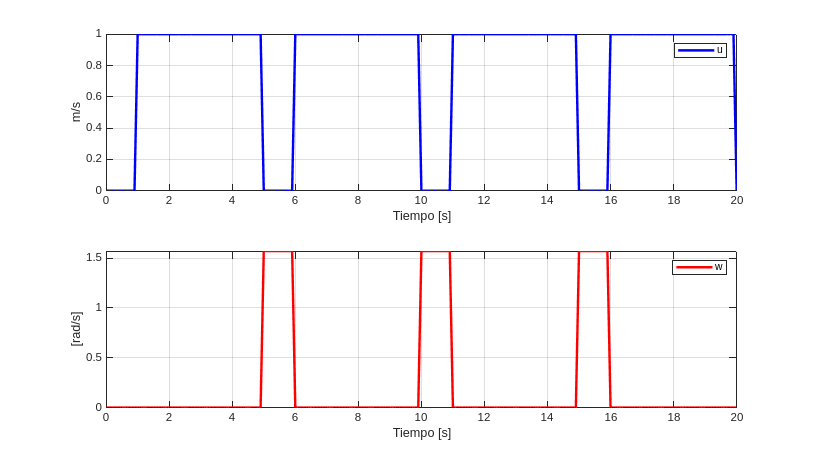


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph = figure;
set(graph, 'position', sizeScreen);
subplot(211)
plot(t, u, 'b', 'LineWidth', 2), grid on, xlabel('Tiempo [s]'), ylabel('m/s'), legend('u');
subplot(212)
plot(t, w, 'r', 'LineWidth', 2), grid on, xlabel('Tiempo [s]'), ylabel('[rad/s]'), legend('w');

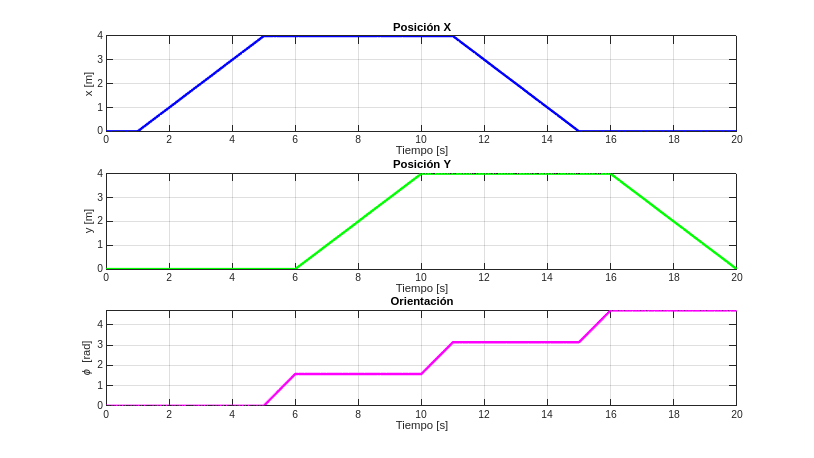


%%%%%%%%%%%%%%%%%%% CÁLCULO DE VELOCIDADES ANGULARES DE LAS RUEDAS %%%%%%%%%%%%%%%%%%%

r = 0.05; % Radio de las ruedas en metros
L = 0.3;  % Distancia entre ruedas (track width) en metros

wl = zeros(1, N);
wr = zeros(1, N);

for k = 1:N
    wl(k) = (2*u(k) - w(k)*L)/(2*r);
    wr(k) = (2*u(k) + w(k)*L)/(2*r);
end

%%%%%%%%%%%%%%%%%%% GRAFICAR POSE Y VELOCIDADES ANGULARES %%%%%%%%%%%%%%%%%%%

pose_graph = figure;
set(pose_graph, 'position', sizeScreen);

subplot(311)
plot(t, x1(1:N), 'b', 'LineWidth', 2), grid on, xlabel('Tiempo [s]'), ylabel('x [m]'), title('Posición X');

subplot(312)
plot(t, y1(1:N), 'g', 'LineWidth', 2), grid on, xlabel('Tiempo [s]'), ylabel('y [m]'), title('Posición Y');

subplot(313)
plot(t, phi(1:N), 'm', 'LineWidth', 2), grid on, xlabel('Tiempo [s]'), ylabel('\phi [rad]'), title('Orientación');

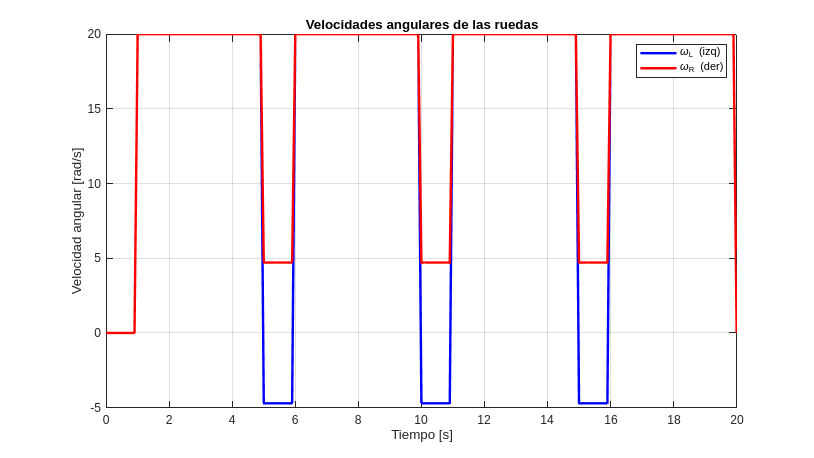


wheel_graph = figure;
set(wheel_graph, 'position', sizeScreen);
plot(t, wl, 'b', 'LineWidth', 2), hold on
plot(t, wr, 'r', 'LineWidth', 2), grid on
xlabel('Tiempo [s]')
ylabel('Velocidad angular [rad/s]')
legend('\omega_L (izq)', '\omega_R (der)')
title('Velocidades angulares de las ruedas')

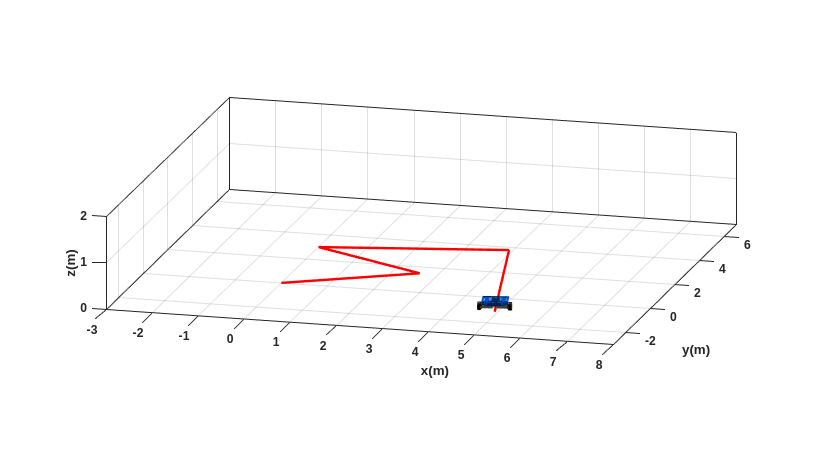

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tf = 20;             % Tiempo de simulacion en segundos (s)
ts = 0.1;            % Tiempo de muestreo en segundos (s)
t = 0: ts: tf;       % Vector de tiempo
N = length(t);       % Muestras

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros (1,N+1);  % Posicion en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros (1,N+1);  % Posicion en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

x1(1) = 0;    % Posicion inicial eje x
y1(1) = 0;   % Posicion inicial eje y
phi(1) =0;   % Orientacion inicial del robot

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1, N+1);  % Posicion en el punto de control (eje x) en metros (m)
hy = zeros(1, N+1);  % Posicion en el punto de control (eje y) en metros (m)

hx(1) = x1(1); % Posicion en el punto de control del robot en el eje x
hy(1) = y1(1); % Posicion en el punto de control del robot en el eje y

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

% Parámetros de los giros y movimientos
angles = [pi/6, pi/1.5, -pi/1.3, -pi/2]; % Ángulos de giro (puedes modificarlos)
distances = [3, 3, 4, 5]; % Distancias de los movimientos lineales en metros (puedes modificarlas)
duration_turn = [1/ts, 1/ts, 1/ts, 1/ts];     % Duración de cada giro (puedes ajustarlo)
duration_lineal = [3, 3, 3, 3]; % Duración de cada movimiento lineal en segundos (puedes ajustarlo)

u = zeros(1,N); % Velocidad lineal (m/s)
w = zeros(1,N); % Velocidad angular (rad/s)

% Generación de las velocidades de referencia
idx_start = 1;
for i = 1:length(angles)
    % Duración del giro
    idx_end_turn = idx_start + duration_turn(i) - 1; % Índice final para el giro, ajustado por duration_turn(i)
    if idx_end_turn <= N
        w(idx_start:idx_end_turn) = angles(i) / (duration_turn(i) * ts); % Giro con el ángulo correspondiente
    end

    % Duración del movimiento rectilíneo
    % Calcular la velocidad lineal basada en la distancia y la duración
    velocity_linear = distances(i) / duration_lineal(i); % Velocidad lineal calculada

    % Duración variable basada en la distancia y la velocidad lineal
    duration_segment = duration_lineal(i) / ts; % Duración en términos de muestras
    idx_start_move = idx_end_turn + 1;
    idx_end_move = idx_start_move + duration_segment - 1; % Duración del movimiento rectilíneo

    if idx_end_move <= N
        u(idx_start_move:idx_end_move) = velocity_linear; % Movimiento rectilíneo con velocidad calculada
    end

    % Actualización de índice para el siguiente giro
    idx_start = idx_end_move + 1;
end


%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N
    phi(k+1)=phi(k)+w(k)*ts;
    xp1=u(k)*cos(phi(k+1));
    yp1=u(k)*sin(phi(k+1));
    x1(k+1)=x1(k) + xp1*ts;
    y1(k+1)=y1(k) + yp1*ts;
    hx(k+1)=x1(k+1);
    hy(k+1)=y1(k+1);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

scene=figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen=get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([15 15]);
axis([-3 8 -3 7 0 2]);

scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

step=1;
for k=1:step:N
    delete(H1);
    delete(H2);
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    pause(ts);
end

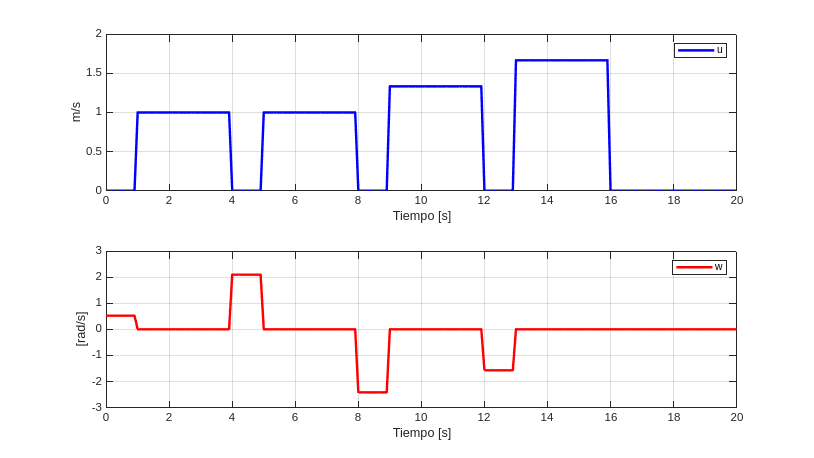


%%%%%%%%%%%%%%%%%%% CÁLCULO DE VELOCIDADES ANGULARES DE LAS RUEDAS %%%%%%%%%%%%%%%%%%%

r = 0.05; % Radio de las ruedas en metros
L = 0.3;  % Distancia entre ruedas (track width) en metros

wl = zeros(1, N);
wr = zeros(1, N);

for k = 1:N
    wl(k) = (2*u(k) - w(k)*L)/(2*r);
    wr(k) = (2*u(k) + w(k)*L)/(2*r);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;
set(graph,'position',sizeScreen);
subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');

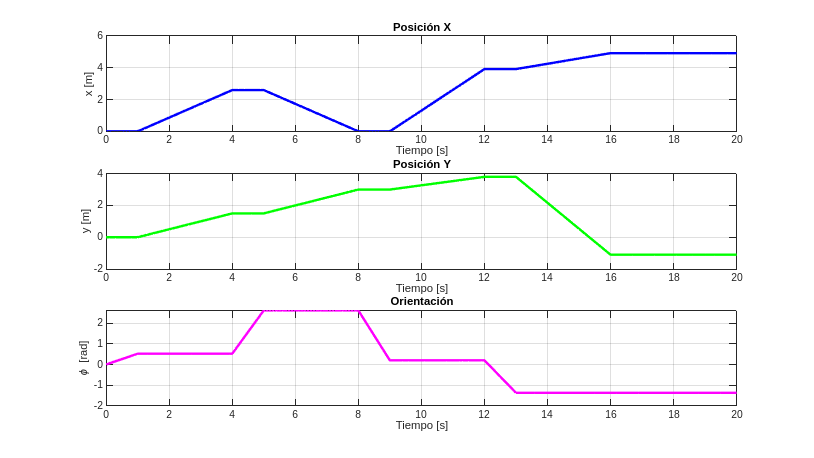


%%%%%%%%%%%%%%%%%%% GRAFICAR POSE Y VELOCIDADES ANGULARES %%%%%%%%%%%%%%%%%%%
pose_graph = figure;
set(pose_graph, 'position', sizeScreen);

subplot(311)
plot(t, x1(1:N), 'b', 'LineWidth', 2), grid on, xlabel('Tiempo [s]'), ylabel('x [m]'), title('Posición X');

subplot(312)
plot(t, y1(1:N), 'g', 'LineWidth', 2), grid on, xlabel('Tiempo [s]'), ylabel('y [m]'), title('Posición Y');

subplot(313)
plot(t, phi(1:N), 'm', 'LineWidth', 2), grid on, xlabel('Tiempo [s]'), ylabel('\phi [rad]'), title('Orientación');

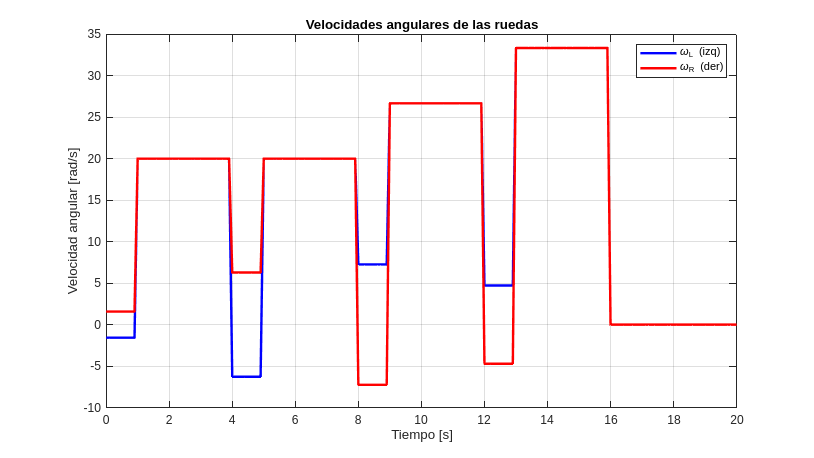

wheel_graph = figure;
set(wheel_graph, 'position', sizeScreen);
plot(t, wl, 'b', 'LineWidth', 2), hold on
plot(t, wr, 'r', 'LineWidth', 2), grid on
xlabel('Tiempo [s]')
ylabel('Velocidad angular [rad/s]')
legend('\omega_L (izq)', '\omega_R (der)')
title('Velocidades angulares de las ruedas')